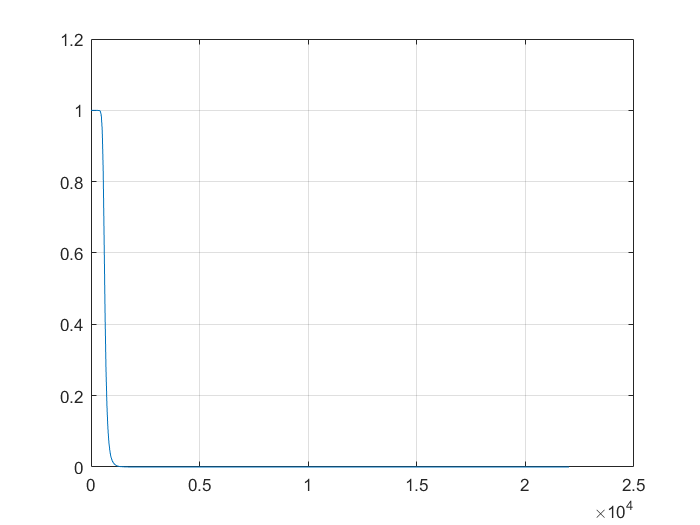

clear sound
[audio,fs]=audioread('ech1.wav');%声音读取
audio = audio(:,1); %双通道变单通道
n=length(audio);
T = 1/fs;%采样间隔
t = (0:n-1)*T;%时间轴
f = (0:n-1)/n*fs;%频率轴
 %快速傅里叶变换
audio_fft=fft(audio,n)*T; 
%sound(audio,fs);

%设计IIR低通滤波器
rp = 1;
rs=60;
Ft=fs;
Fp=250;
Fs=700;                                        
wp=2*pi*Fp/Ft;
ws = 2*pi*Fs/Ft ;   %求出待设计的模拟滤波器的边界频率
[N,wn]=buttord(wp,ws,rp,rs,'s');    %低通滤波器的阶数和截止频率
[b,a]=butter(N,wn,'s');             %S域频率响应的参数即：滤波器的传输函数
[bz,az]=bilinear(b,a,0.5);          %利用双线性变换实现频率响应S域到Z域的变换
figure(2);%低通滤波器特性
[h,w]=freqz(bz,az);
title('IIR低通滤波器');
plot(w*fs/(2*pi),abs(h));
grid;

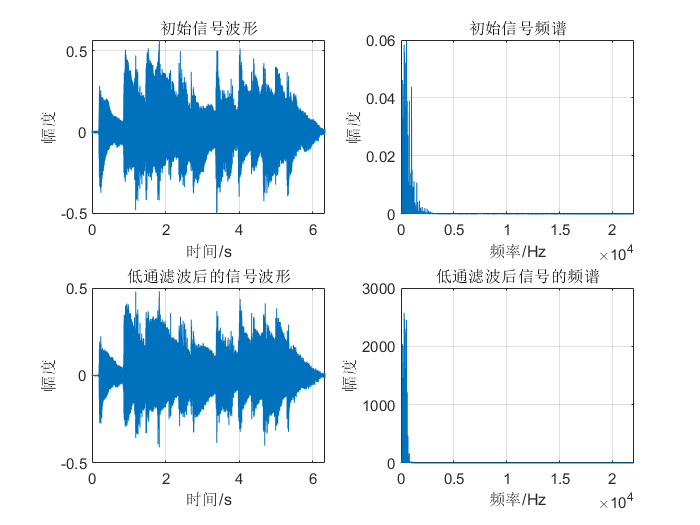


%滤波
z=filter(bz,az,audio);
z_fft=fft(z);     %滤波后的信号频谱
figure(1); 
%绘出原始音频时域波
subplot(2,2,1);
plot(t,audio);   
xlabel('时间/s');
ylabel('幅度');
title('初始信号波形');  
grid;

 %绘出原始音频频域频谱
subplot(2,2,2); 
audiof = abs(audio_fft);
plot(f(1:(n-1)/2),audiof(1:(n-1)/2));
title('初始信号频谱');
xlabel('频率/Hz');
ylabel('幅度');
grid;

%绘出滤波音频时域波
subplot(2,2,3);
plot(t,z);
title('低通滤波后的信号波形');
xlabel('时间/s');
ylabel('幅度');
grid;

%绘出滤波音频频域波
subplot(2,2,4);
zf = abs(z_fft);
plot(f(1:(n-1)/2),zf(1:(n-1)/2));
title('低通滤波后信号的频谱');
xlabel('频率/Hz');
ylabel('幅度');

y = z;
% info = audioinfo ('ech1.wav');% get the audio format, number of bits, frequency, etc.
 sound (y, fs);
T = 1 / fs;% sampling time
t = (0: length (y) -1) * T;% time
f = (0: length (y) -1) * fs / length (y);
yz = y (:, 1);% left channel
n = length (yz);% points to transform
y1 = fft (yz, n);% Fourier transform n points to frequency domain
F = fs / length (yz);% spectral resolution, spectral interval
grid on

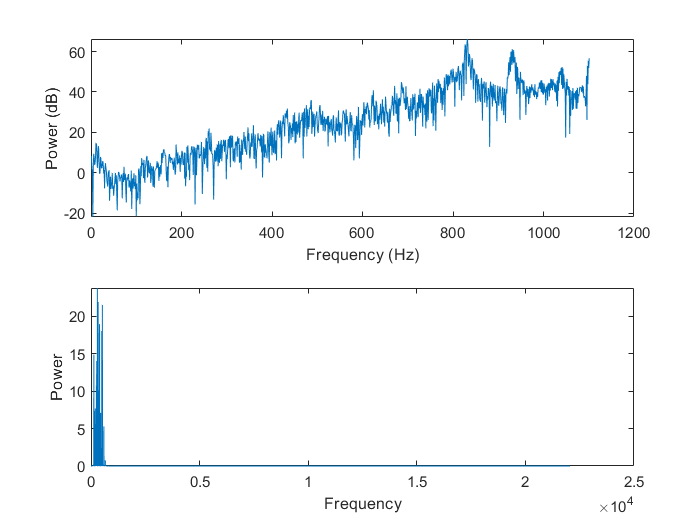

figure (2)
subplot (211);
Pyy = y1 (1: 1100 + 1);% according to the way of processing vector to get the range of the required sound signal
f = (1: 1100 + 1);
plot (f, 20 * log10 (abs (Pyy)))% energy spectrum
xlabel ('Frequency (Hz)')
ylabel ('Power (dB)')
subplot (212)
bar (f, abs (Pyy))% energy graph


n = length(audio);          % number of samples
f = (0:n-1)*(fs/n);     % frequency range
power = abs(y1).^2/n;    % power of the DFT

plot(f(1:(n-1)/2),power(1:(n-1)/2))
xlabel('Frequency')
ylabel('Power')

subplot(2,1,1)

spectrogram(z,256,[],256,fs,'yaxis')

错误使用 welchparse>segment_info (line 228)
The number of samples to overlap must be less than the length of the segments.

出错 welchparse (line 32)
[L,noverlap,win] = segment_info(M,win,noverlap);

出错 pspectrogram (<a href="matla

subplot(2,1,2)
wavEnergy=z(:,1);
time=(1/fs)*length(wavEnergy);
t=linspace(0,time,length(wavEnergy));
plot(t,wavEnergy);